%% trainBeamNet.mlx – Train & Evaluate MLP for Beam Index Prediction

%% 1. Load Dataset
if ~isfile('beamDataset28GHz.mat')
    error('Dataset not found. Run generateDataset.mlx first.');
end
data = load('beamDataset28GHz.mat');
X    = data.features;            % 10000×256
Y    = categorical(data.labels); % 10000×1

%% 2. Split into Train/Val/Test
N      = size(X,1);
rng(0);                         % reproducible
idx    = randperm(N);
nTrain = floor(0.7*N);
nVal   = floor(0.15*N);

iTrain = idx(1:nTrain);
iVal   = idx(nTrain+1 : nTrain+nVal);
iTest  = idx(nTrain+nVal+1 : end);

XTrain = X(iTrain,:);  YTrain = Y(iTrain);
XVal   = X(iVal,:);    YVal   = Y(iVal);
XTest  = X(iTest,:);   YTest  = Y(iTest);

%% 3. Define MLP Architecture
inputSize  = size(XTrain,2);      % 256
numClasses = numel(categories(YTrain));  % 64

layers = [
    featureInputLayer(inputSize,'Name','input')
    fullyConnectedLayer(128,'Name','fc1')
    reluLayer('Name','relu1')
    fullyConnectedLayer(128,'Name','fc2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(numClasses,'Name','fc3')
    softmaxLayer('Name','softmax')
    classificationLayer('Name','output')
];

%% 4. Training Options
options = trainingOptions('adam', ...
    'MaxEpochs',20, ...
    'MiniBatchSize',128, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{XVal,YVal}, ...
    'ValidationFrequency',floor(nTrain/128), ...
    'Verbose',false, ...
    'Plots','training-progress');

%% 5. Train Network
net = trainNetwork(XTrain,YTrain,layers,options);

%% 6. Test & Visualize
YPred = classify(net,XTest);
acc   = mean(YPred==YTest);
disp(['🏁 Test Accuracy: ' num2str(acc*100,'%.2f') '%']);

🏁 Test Accuracy: 2.07%


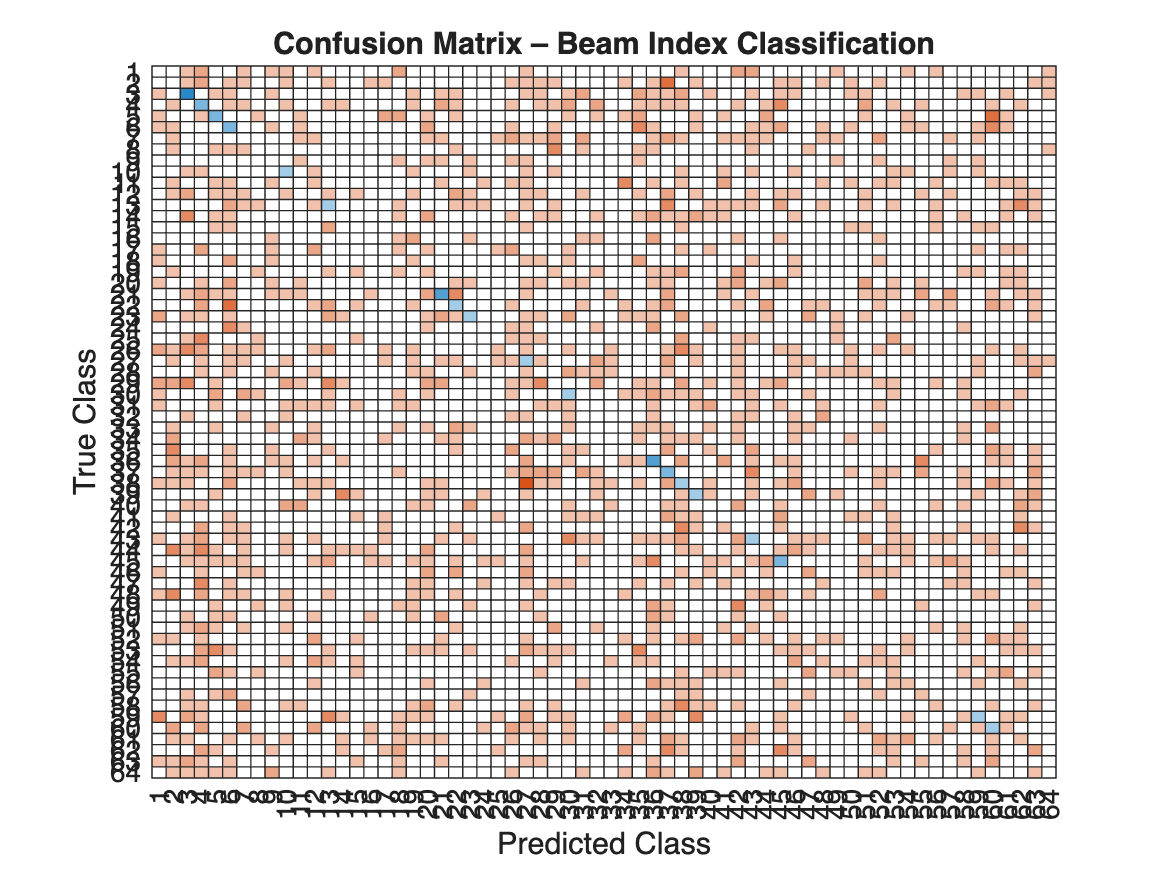


figure;
confusionchart(YTest,YPred);
title('Confusion Matrix – Beam Index Classification');